clc
clear

TTDmatrix = readmatrix("C:\Users\admin\Desktop\Particles2D\TTD.txt");
%TTDmatrix = readmatrix("C:\Users\admin\Desktop\EdgeParticle2D\TTD.txt")
height = size(TTDmatrix, 1)

height = 11

width = size(TTDmatrix,2)

width = 50000

TTDx = linspace(0,height,height);
TTDx = linspace(0,width, width);
TTDx = TTDx(2:end);
TTD = TTDmatrix(2:end);


% Constants
deltax = 1/200

deltax = 0.0050

deltay = 1/200

deltay = 0.0050

D_2d = (deltax^2 + deltay^2) / 4 %2 D deltat * degrees of freedom.

D_2d = 1.2500e-05

r_int = 0.05;
k_on = 1; %Kan fjernes med analytisk approximation
l_DNA = r_int^2*pi;
l_DNA = 1;
n = 1

n = 1

N = 3;

% Define Bessel function ratios correctly
K0 = @(s) besselk(0, sqrt(s / D_2d) * r_int);
K1 = @(s) besselk(1, sqrt(s / D_2d) * r_int);
K_1_div_K_0 = @(s) K1(s) ./ K0(s);

% Handle small K0 cases
%small_s_idx = abs(K0(1e-6)) < 1e-6; % Threshold near zero
%if small_s_idx
%    K_1_div_K_0 = @(s) 1 ./ s; % Approximate behavior as s -> 0
%end

% Define Laplace-space function
%F_s_fun2 = @(s) (k_on * l_DNA ./ s.^2) .* (1 + (k_on) ./ (2 * pi * sqrt(s / D_3d) * r_int .* K_1_div_K_0(s))).^(-1);
F_s = @(s) (r_int ./(l_DNA * s.^2)) .* (2 * pi * sqrt(s * D_2d) ) .* K_1_div_K_0(s);
%F_s = @(s) (r_int*k_on) / (s^2 * pi*r_int^2)*((k_on)/(2 * pi * r_int)*K_1_div_K_0(s));
%F_s = @(s) (2 * pi * r_int * n * sqrt(1./(D_2d .* s)) .* (K_1_div_K_0(s)));
% Inverse Laplace Transform using Talbot method
%Edge function.
%F_s = @(s) 1/s * r_int * (1-sqrt(s * D_2d)*2*pi*r_int*K_1_div_K_0(s))^-1

TalbotInverse = @(t) Talbot(F_s, t, 8);
P_surv = @(t) exp(-TalbotInverse(t))^N;

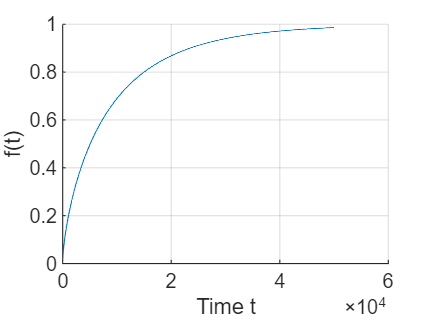

%P_before_talbot = @(s) exp(-F_s(s))
%P_talbot = @(t) Talbot(P_before_talbot, t, 8);
%P_talbot_func = arrayfun(P_talbot, TTDx)




P_surv_func = arrayfun(P_surv,TTDx);




%P_surv_func = P_talbot_func
F_s_func = arrayfun(F_s, TTDx);
Talbot_debug = arrayfun(TalbotInverse, TTDx);


% Plot
figure;
hold on
%plot(t_vals, f_t_vals, 'r', 'LineWidth', 2);
plot(TTDx,1-P_surv_func);
xlabel('Time t');
ylabel('f(t)');
%title('Numerical Inverse Laplace Transform');
grid on;
hold off

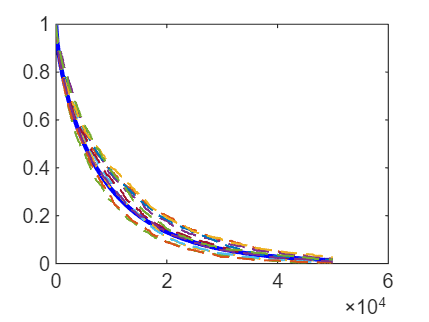



figure;
plot(TTDx,P_surv_func, 'b','DisplayName','Numeric solution', LineWidth=2)
hold on
for i = 1:height
TTD = TTDmatrix(i,2:end);
plot(TTDx,(1000-TTD)/1000, LineWidth=1, LineStyle="--");
end

hold off